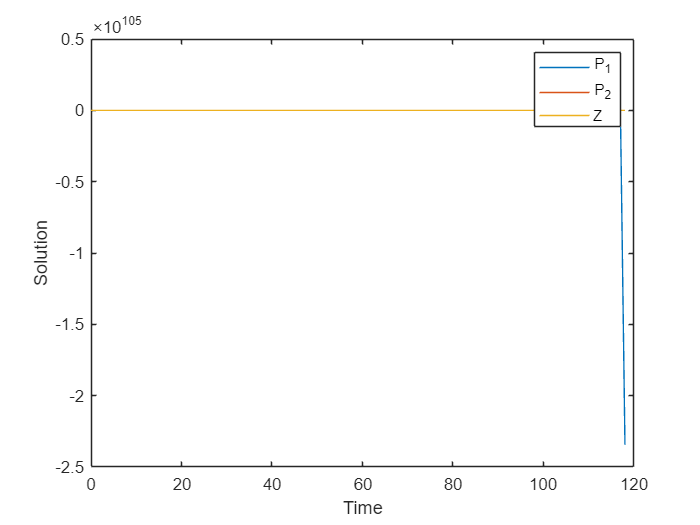

clc;
clear;
% 定义时间步长和时间范围
h = 1; % 时间步长
t0 = 0; % 初始时间
tf = 1000; % 终止时间
t = t0:h:tf; % 时间向量

%初始化参数
r = 0.2;
a = 0.04;
u = 0.2;
b = 0.6;
e1 = 0.03;
e2 = 0.03;
s = 0.04;
k = 0.05;
w1 = 0.05;
w2 = 0.05;
lambda = 0.035;
mu = 0.06;
alpha = 0.25;
beta = 0.25;
N0 = 0.7142;
K = 5;
Z0 = 0.005;

% 初始化解向量
y = zeros(3, length(t)); 
y(:, 1) = [1.4746; 0.3349;0]; % 初始条件

% 定义方程组
f = @(t, y) [
    r*y(1)*(1-y(1)/K)-a*y(1)*y(3)/(lambda+y(1))-w1*y(1)+w2*y(2)-(s+k)*y(1);
    u*y(2)-b*y(2)*y(3)-w2*y(2)+w1*y(1)-(s+k)*y(2);
    (alpha*a*y(1)/(lambda+y(1))+beta*b*y(2))*y(3)-mu*y(3);
];

% RK4 方法
for i = 1:length(t)-1
    k1 = h * f(t(i), y(:, i));
    k2 = h * f(t(i) + h/2, y(:, i) + k1/2);
    k3 = h * f(t(i) + h/2, y(:, i) + k2/2);
    k4 = h * f(t(i) + h, y(:, i) + k3);
    y(:, i+1) = y(:, i) + (k1 + 2*k2 + 2*k3 + k4) / 6;
end

% 绘制结果
plot(t, y);
legend('P_1', 'P_2','Z');
xlabel('Time');
ylabel('Solution');